Plot values from strain gauge test

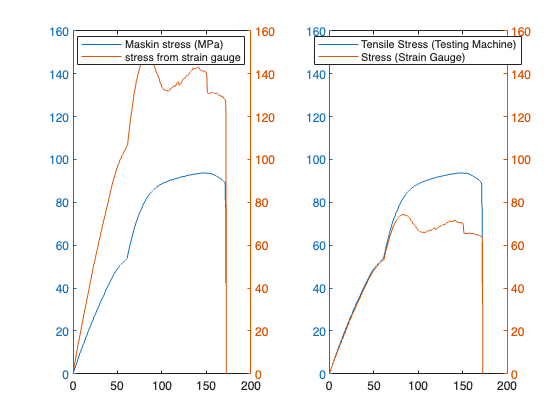

% Les filer
machine = readtable("maskin.csv");
gauge   = readtable("strain_gauge.csv");

%Zero maskindata
machine.TensileStress = machine.TensileStress-machine.TensileStress(1);

%Fiks tidsaksen på gauge måling
gauge = gauge(368:842,:);
gauge.Time = (gauge.Time - gauge.Time(1))/1000;

%Fiks feil strain måling
fixedMicroStrain = gauge.microStrain/2;


%Strain måling om til stress
E = 73000; % MPa
strain = gauge.microStrain / 1e6;
fixedstrain = fixedMicroStrain/ 1e6;
stress = E * strain; %MPa
fixedstress = E*fixedstrain; %MPa

figure
tiledlayout(1,2)

ygrense = 160;

% Ukorrekt plot
nexttile
yyaxis left
plot(machine.Time, machine.TensileStress, 'DisplayName', 'Maskin stress (MPa)');
ylim([0,ygrense])

yyaxis right
plot(gauge.Time, stress, 'DisplayName', 'stress from strain gauge')
ylim([0,ygrense])

legend('Location','best')

% Korrekt plot
nexttile
yyaxis left
plot(machine.Time, machine.TensileStress, 'DisplayName', 'Tensile Stress (Testing Machine)');
ylim([0,ygrense])

yyaxis right
plot(gauge.Time, fixedstress, 'DisplayName', 'Stress (Strain Gauge)')
ylim([0,ygrense])
legend('Location','best')




% Interpoler strain gauge stress til maskinens tid
offsett = - 0.7;
stress_interp = interp1(gauge.Time + offsett, fixedstress, machine.Time, "linear", NaN);
strain_interp = interp1(gauge.Time + offsett, fixedstrain, machine.Time, "linear", NaN);

% Velg elastisk område på machine.Time
idx = machine.Time > 10 & machine.Time < 60;

% Sammenlign samme indekslengde
ratio = machine.TensileStress(idx) ./ stress_interp(idx);

mean_ratio = mean(ratio, "omitnan")

mean_ratio = 1.0065

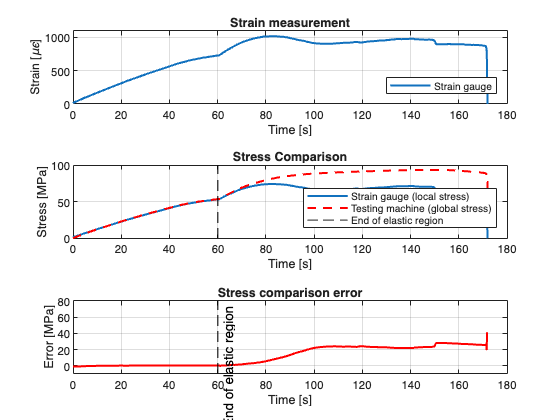



fig = figure;
tiledlayout(3,1)
% Plot strain gauge measurement
nexttile
plot(machine.Time, strain_interp*1e6,'LineWidth', 1.5, 'DisplayName', 'Strain gauge')
xlabel('Time [s]')
ylabel('Strain [\mu\epsilon]')
legend('Location','southeast')
ylim([0,1100])
grid on 
title('Strain measurement')

% Plot stress comparison
nexttile
plot(machine.Time, stress_interp,'LineWidth',1.5, 'DisplayName', 'Strain gauge (local stress)')
hold on
plot(machine.Time, machine.TensileStress, '--r', 'LineWidth',1.5, 'DisplayName', 'Testing machine (global stress)')
legend('Location','southeast')
ylabel("Stress [MPa]")
xlabel("Time [s]")
title('Stress Comparison')
xline(60, '--k', '', 'LineWidth', 1, 'DisplayName','End of elastic region')
grid on

% Stress error
valid = ~isnan(stress_interp) & machine.Time < 171.7;
error = machine.TensileStress(valid) - stress_interp(valid);

% Plot error
nexttile
plot(machine.Time(valid), error, 'r', 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Error [MPa]')
title('Stress comparison error')
xline(60, '--k', 'End of elastic region', 'LineWidth', 1, 'DisplayName','End of elastic region')
ylim([-10,80])
grid on

## Export figure with preset size

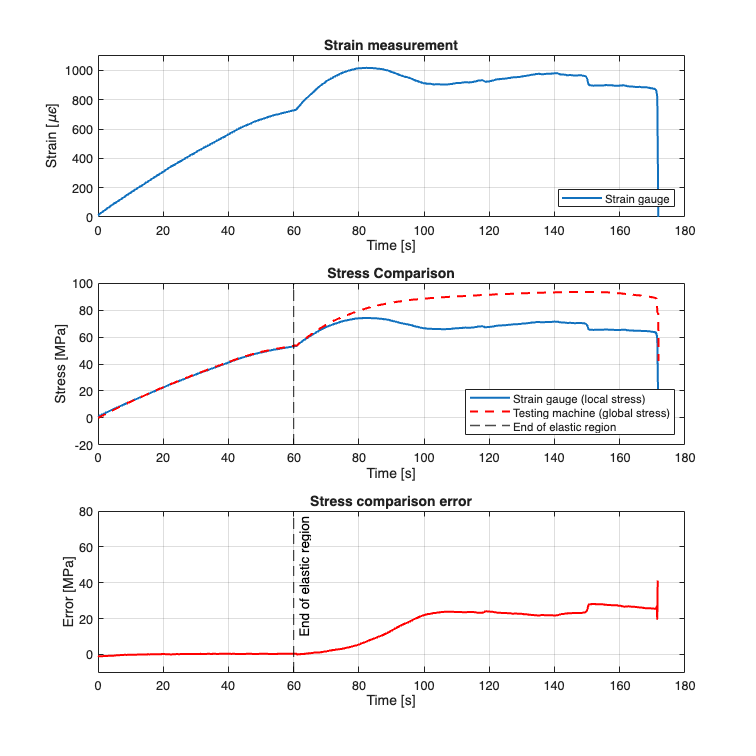

% Desired output size (inches) and resolution (DPI)
fig = gcf;
set(fig, 'WindowStyle', 'normal')
fig.Units = 'centimeters';
fig.Position = [2 2 20 20];
set(fig,'PaperPositionMode','auto')
print(fig,'plots.png','-dpng','-r300')